clear
close all
clc
format longg

% Set MICE and SPICE data paths
miceDir='mice\';
spiceDataDir='spice\';

if(length(strfind( miceDir , '<<ENTER_PATH>>' )))
    error('enter miceDir path')
end
if(length(strfind( spiceDataDir , '<<ENTER_PATH>>' )))
    error('enter spiceDataDir path')
end

addpath([miceDir 'lib'])
addpath([miceDir 'src\mice\'])

% bsp files for Mars, Deimos, and the Sun
cspice_furnsh([spiceDataDir 'mar097.bsp'])

% orientation info for bodies
cspice_furnsh([spiceDataDir 'pck00011.tpc'])

% leap second information
cspice_furnsh([spiceDataDir 'naif0012.tls'])

% Initialise necessary variables
ET_initial = cspice_str2et('May 01, 2023 03:00 PM CDT');
OE_initial = [16, 0.125, 0, 0, 0, 0];
R_deimos = 6.25;
Sun = 'SUN';
Mars = '499';
Deimos = '402';
rf = 'ECLIPJ2000';
abcorr = 'NONE';
Mu_deimos = 9.85e-5;
Mu_mars = 4.282837362069909e4;
Mu_sun = 1.327124400409446e11;
frame1 = 'ECLIPJ2000';
frame2 = 'IAU_DEIMOS';

% Rotatioin matrix from Inertial 'EclipJ2000' to
% non-inertial 'IAU_DEIMOS' frozen at ET_initial,
% becoming an inertial frame
R_1to3 = cspice_pxform(frame1, frame2, ET_initial);
R_3to1 = cspice_pxform(frame2, frame1, ET_initial);

J = [0; 10.79; -2.566; -1.524]/10^2;
C = [0, 0, 0, 0;
     -0.0939, 3.081, 0, 0;
     1.545, -0.379, -0.0168, 0;
     -0.629, -0.116, 0.0680, 0.0254]/10^2;
S = [0, 0, 0, 0;
     0.468, 0.0791, 0, 0;
     0.0562, -0.170, 0.101, 0;
     0.0244, 0.154, -0.0367, -0.00579]/10^2;

% Create P structure
P.R_deimos = R_deimos;
P.Mu_deimos = Mu_deimos;
P.Mu_mars = Mu_mars;
P.Mu_sun = Mu_sun;
P.J = J;
P.C = C;
P.S = S;
P.R_1to3 = R_1to3;
P.R_3to1 = R_3to1;
P.mode = 1;
P.ET_initial = ET_initial;

2) Gravity field validation

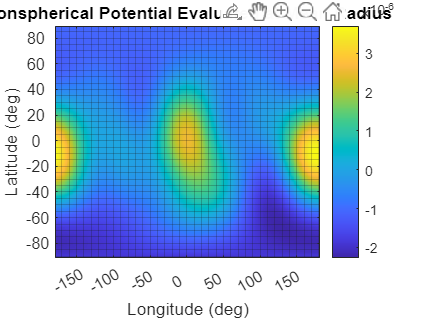

% Validating J, C, and S terms
J_sum = sum(J(:));
C_sum = sum(sum(C(:,:)));
S_sum = sum(sum(S(:,:)));

% Validating gravity field with color map
lat = -90:1:90;
long = -180:1:180;
U_validation = zeros(length(lat),length(long));

for i = 1:length(lat)
    for j = 1:length(long)
        x = R_deimos*cos(lat(length(lat)-i+1)*pi/180)*cos(long(j)*pi/180);
        y = R_deimos*cos(lat(length(lat)-i+1)*pi/180)*sin(long(j)*pi/180);
        z = R_deimos*sin(lat(length(lat)-i+1)*pi/180);
        x_vec = [x, y, z];
        [~, U_validation(i,j)] = SHacc4x4only(x_vec, R_deimos, Mu_deimos, J, C, S);
    end
end

GravityFieldValidation = figure;
imagesc(U_validation)
ax=gca;
ax.XTick = 30:50:330;
ax.XTickLabel = [-150, -100, -50, 0, 50, 100, 150];
ax.YTick = 10:20:170;
ax.YTickLabel = [80, 60, 40, 20, 0, -20, -40, -60, -80];
ax.MinorGridLineStyle = "-";
ax.XMinorGrid = "on";
ax.YMinorGrid = "on";
colorbar
xlabel('Longitude (deg)')
ylabel('Latitude (deg)')
title('Nonspherical Potential Evaluated at Mean Radius')

3) Simulation validation

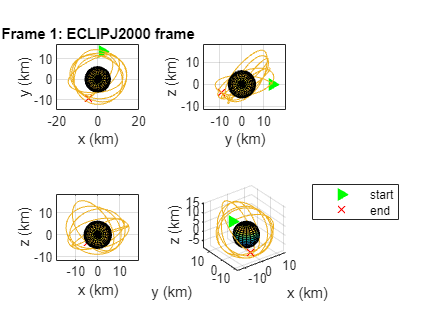

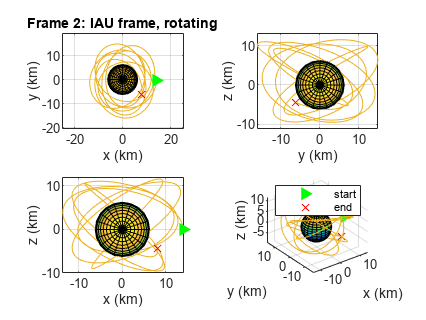

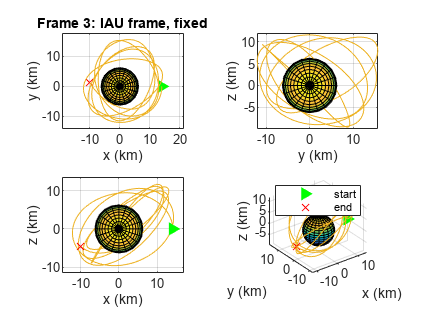

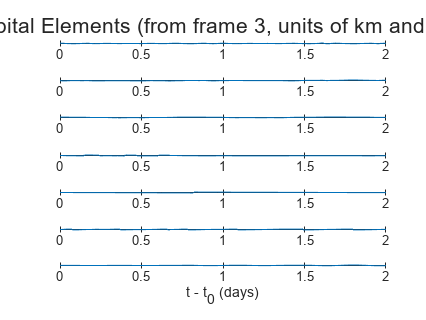

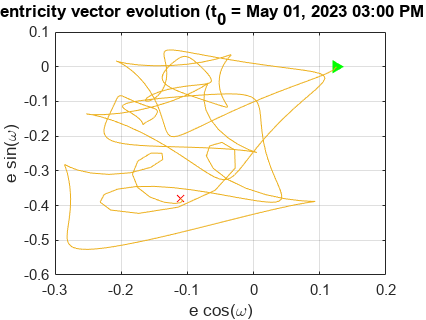

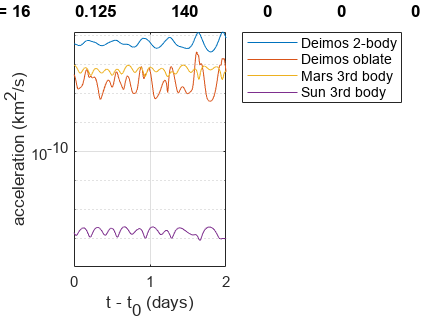

% Validating simulation
TOF = 2;
OE_initial(3) = 140;
runAndPlot(TOF, OE_initial, P)

4)

ET_initial % Ephemeris time at t0

ET_initial =           736243269.185476


R_1to3 % Rotation matrix from frame 1 to frame 3

R_1to3 =          0.169913857132807         0.985458455864614      0.000955468043667362
        -0.897202976211888         0.154295553643654         0.413787024448965
         0.407622497699504       -0.0711653981280846         0.910373212192938


R_3to1 % Rotation matrix from frame 3 to frame 1

R_3to1 =          0.169913857132807        -0.897202976211888         0.407622497699504
         0.985458455864614         0.154295553643654       -0.0711653981280846
      0.000955468043667362         0.413787024448965         0.910373212192938


5) i0 = 179 deg and ToF = 5 days

a) Full

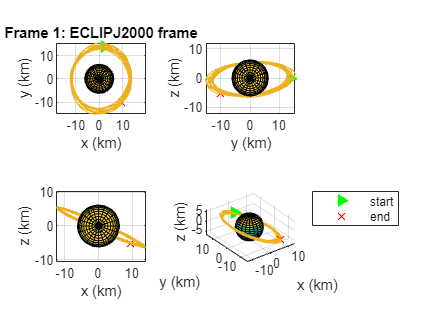

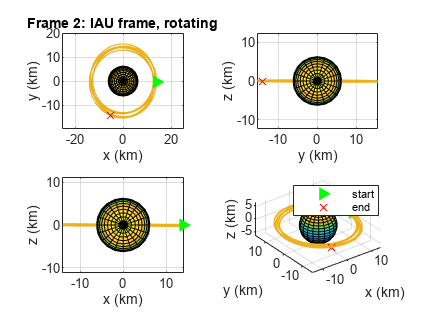

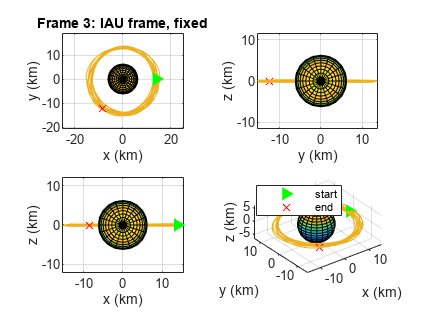

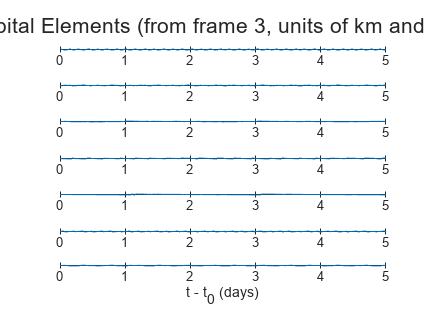

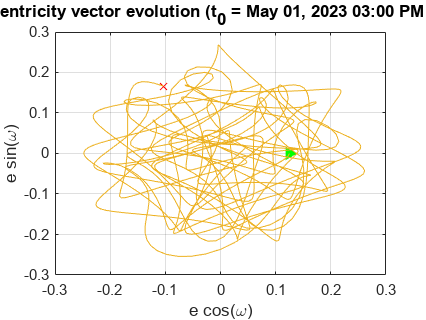

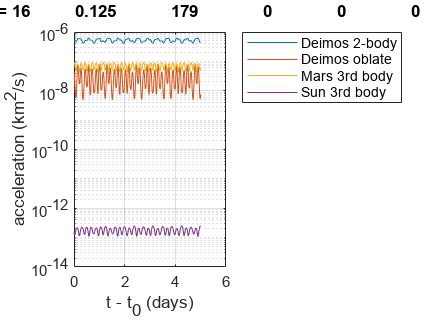

TOF = 5;
OE_initial(3) = 179;

runAndPlot(TOF, OE_initial, P)

b) Deimos two body only

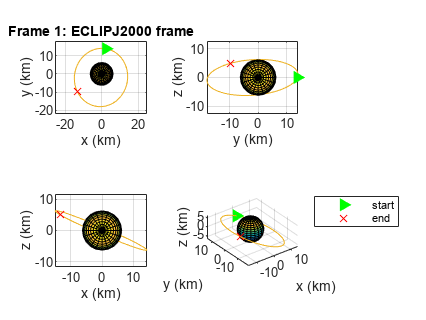

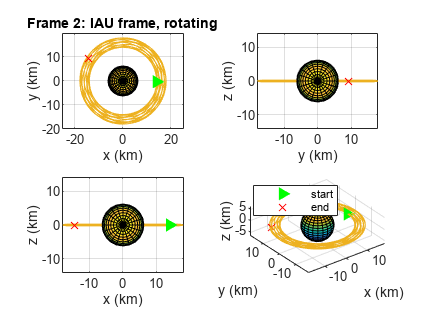

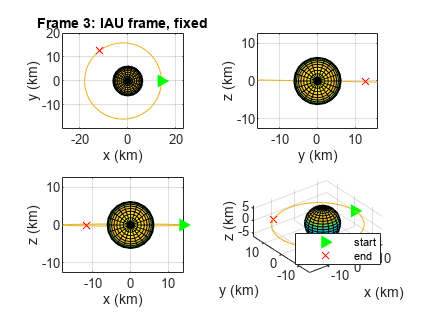

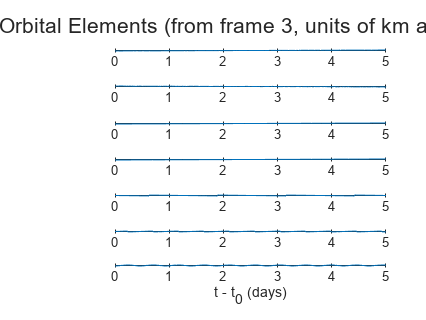

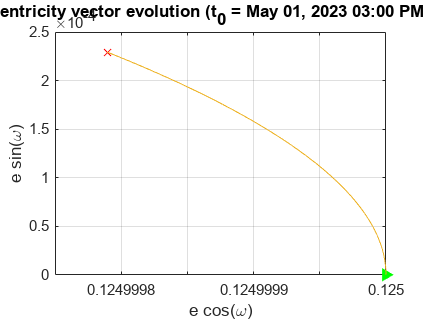

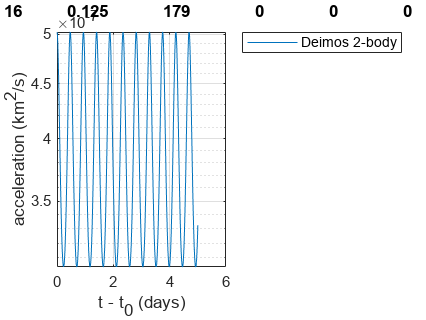

P.mode = 2;
runAndPlot(TOF, OE_initial, P)

c) Deimos two body plus nonspherical only

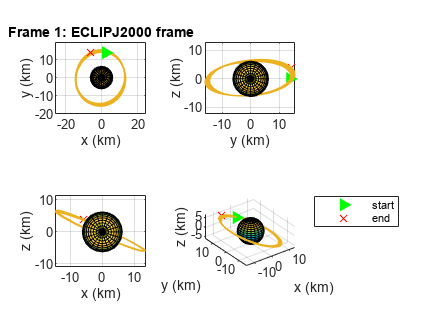

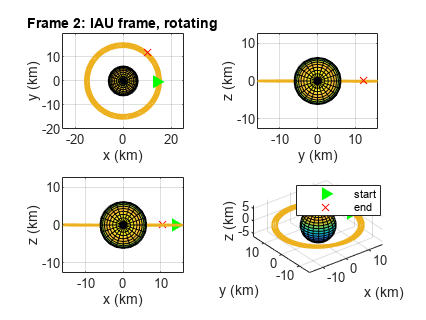

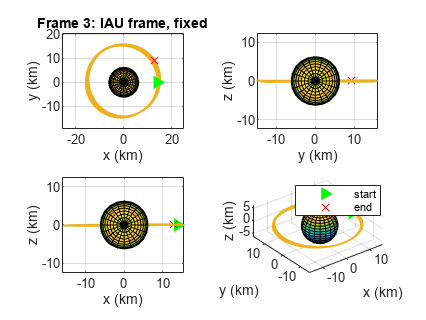

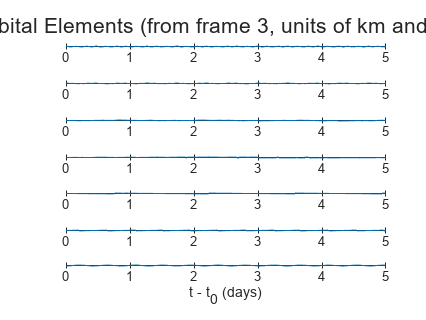

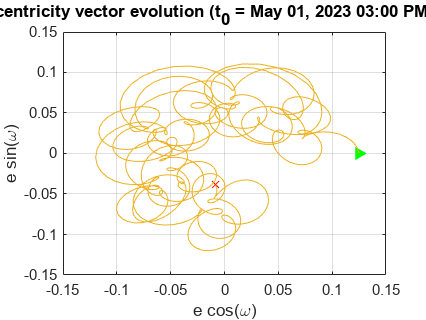

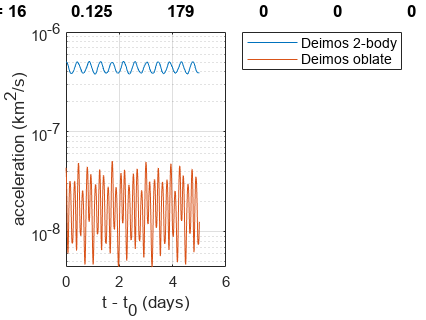

P.mode = 3;
runAndPlot(TOF, OE_initial, P)

d) Deimos two body plus Mars and Sun third body only

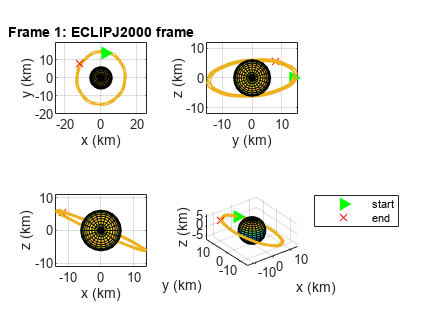

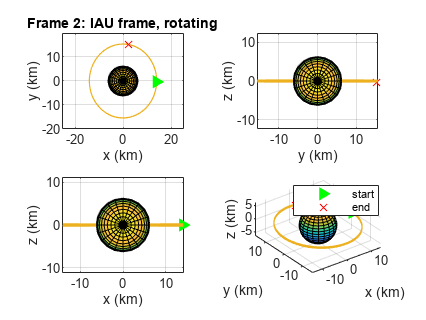

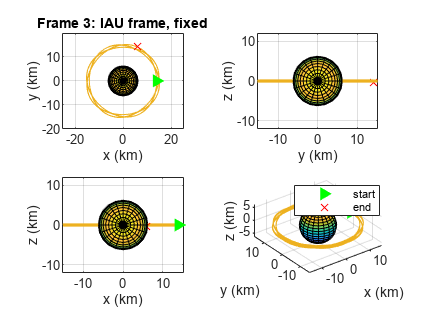

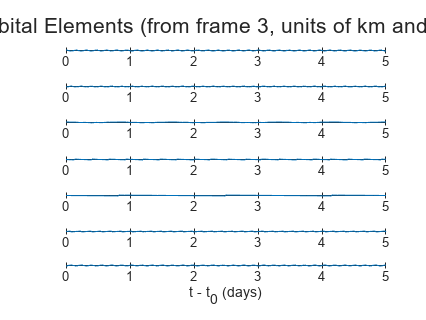

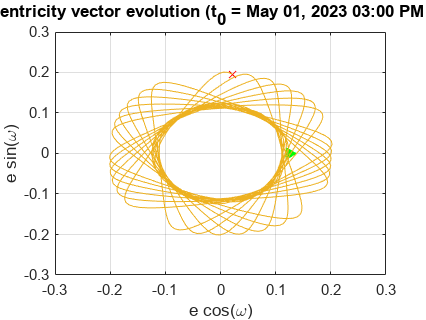

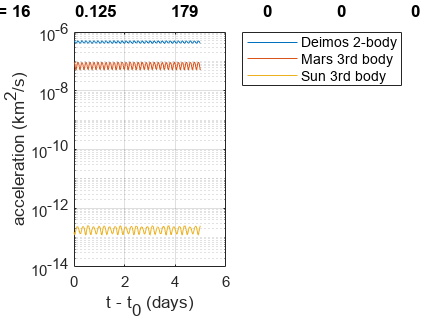

P.mode = 4;
runAndPlot(TOF, OE_initial, P)

6) i0 = 110 deg and ToF = 5 days

a) Full

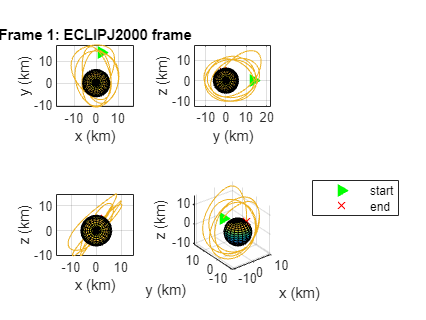

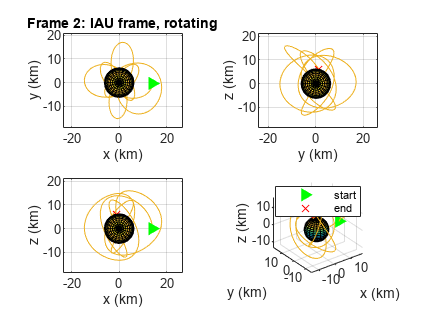

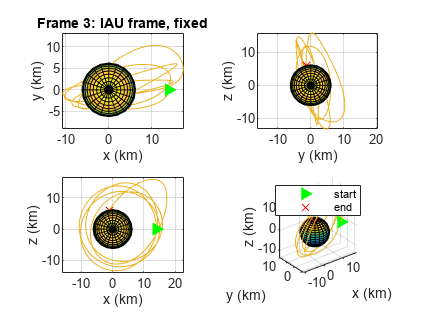

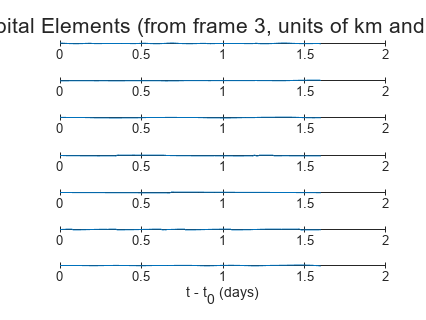

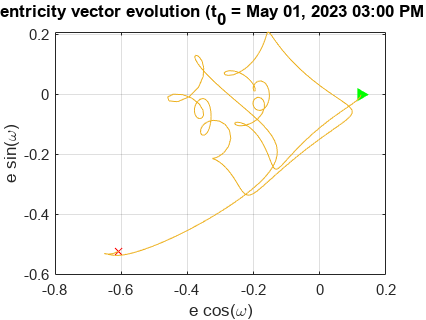

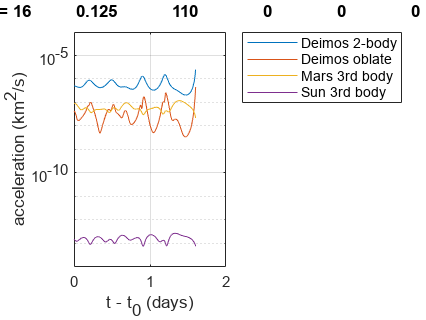

TOF = 5;
OE_initial(3) = 110;
P.mode = 1;
runAndPlot(TOF, OE_initial, P)

b) Deimos two body only

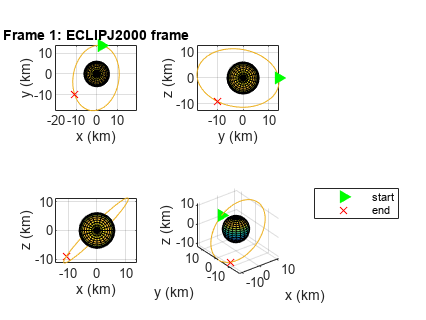

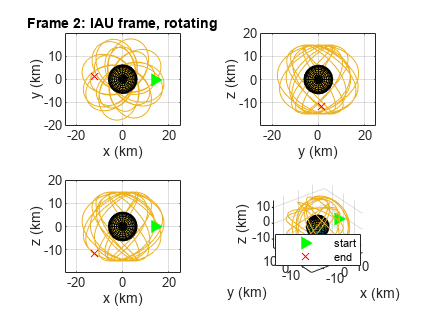

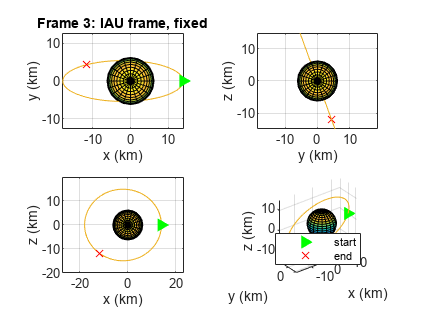

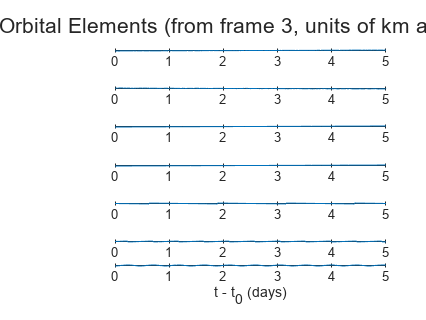

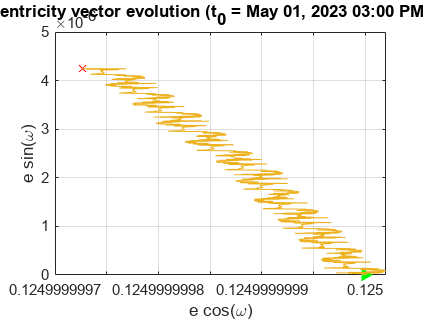

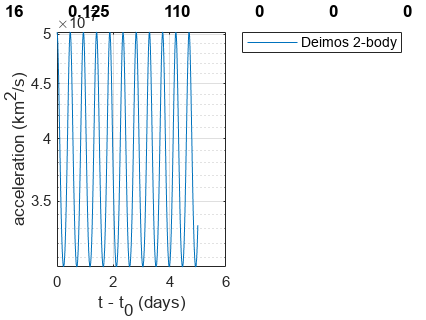

P.mode = 2;
runAndPlot(TOF, OE_initial, P)

c) Deimos two body plus nonspherical only

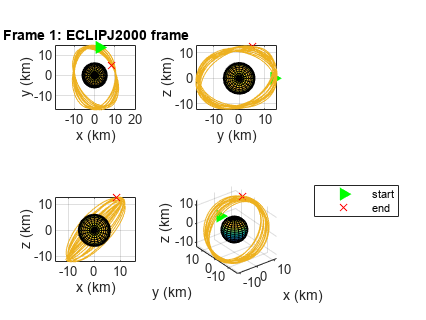

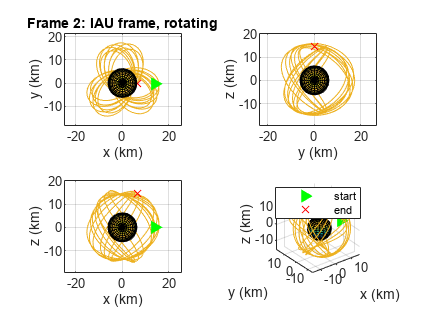

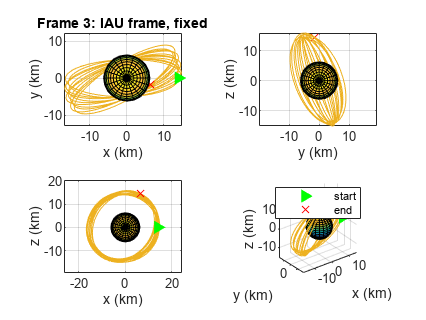

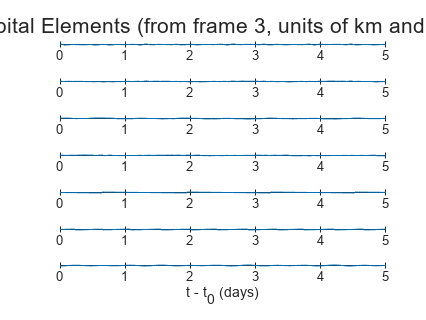

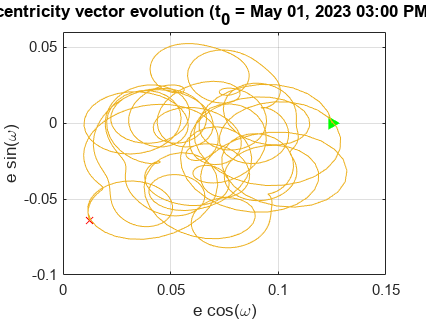

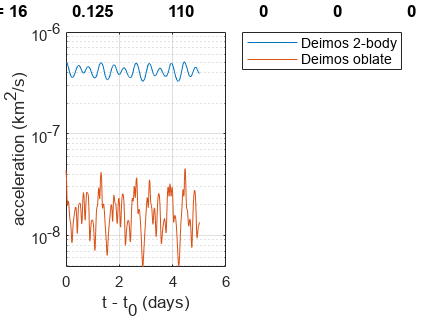

P.mode = 3;
runAndPlot(TOF, OE_initial, P)

d) Deimos two body plus Mars and Sun third body only

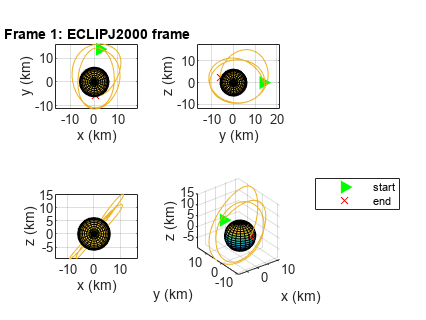

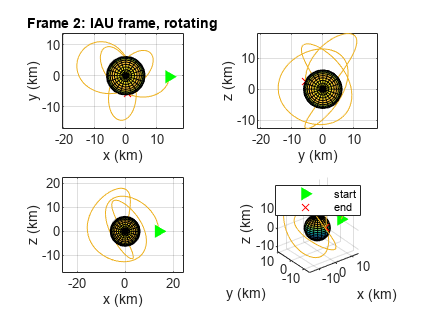

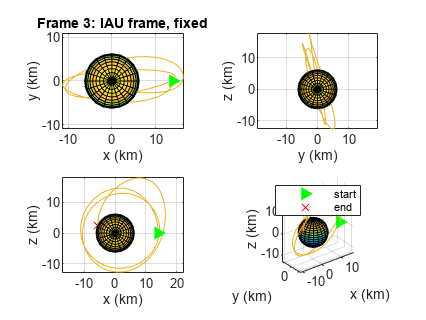

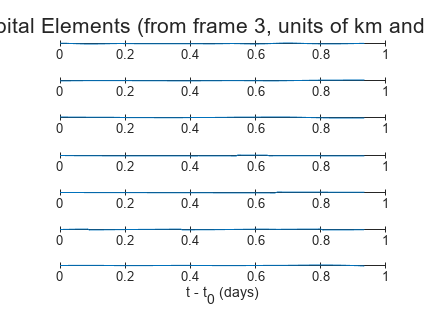

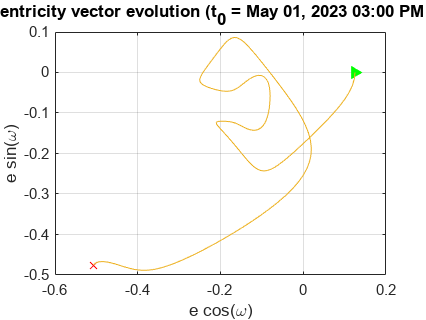

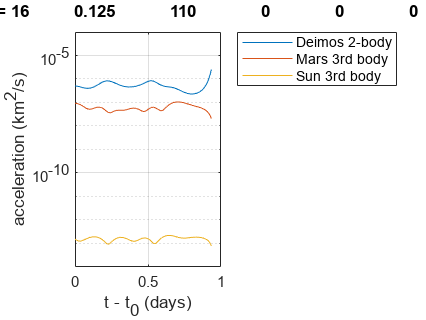

P.mode = 4;
runAndPlot(TOF, OE_initial, P)

7) Full force model with i0 = 179 deg and ToF = 90 days

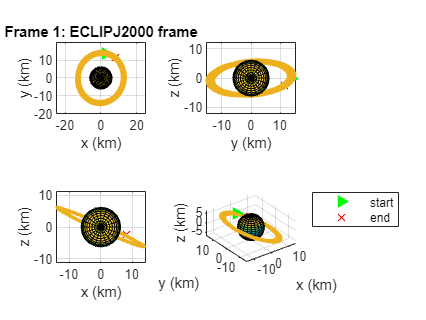

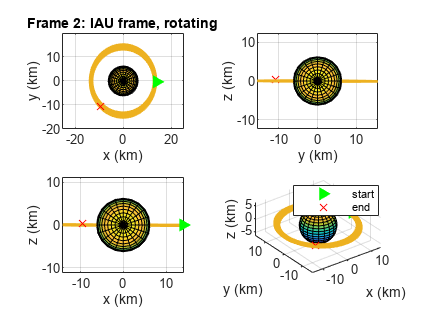

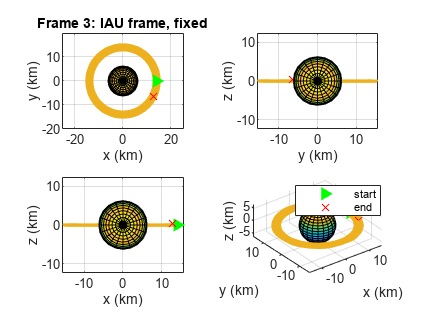

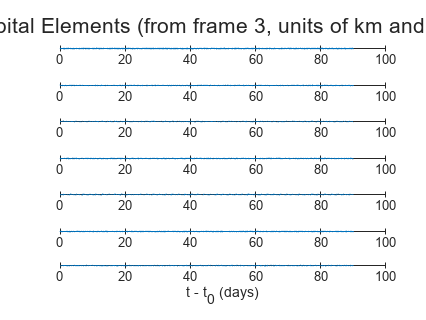

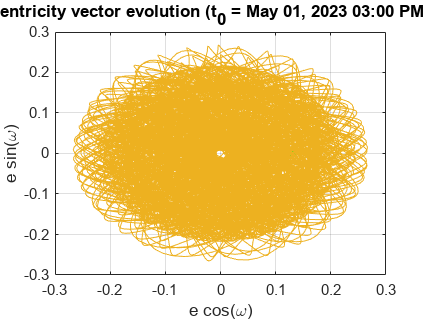

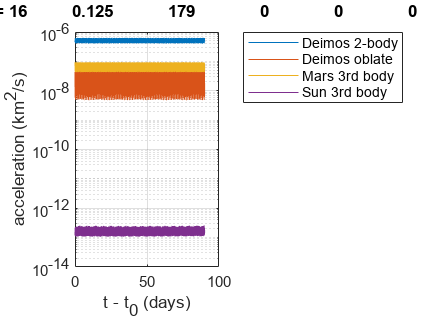

TOF = 90;
OE_initial(3) = 179;
P.mode = 1;

runAndPlot(TOF, OE_initial, P)

8) 

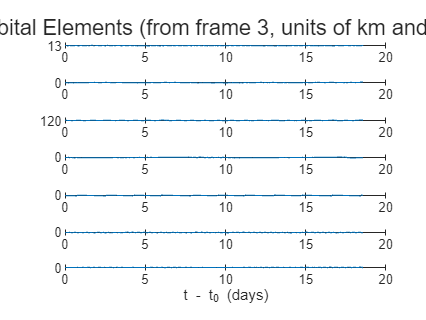

TOF = 20;
OE_initial(3) = 179;
P.mode = 1;
X_initial = oe2vec(OE_initial, Mu_deimos);
X_initial(1:3) = R_3to1*X_initial(1:3);
X_initial(4:6) = R_3to1*X_initial(4:6);
tspan = linspace(ET_initial, (ET_initial+TOF*24*60*60), 200);
options = odeset('RelTol',1e-10,'AbsTol',1e-10,'Event',@meanRadiusFct);
Xdot = @(t, X)propagateOrbit(X, t, P);
while true
    [tVec, X, te, ye, ie] = ode45(Xdot, tspan, X_initial, options);
    if te
        break
    end
    OE_initial(3) = OE_initial(3) - 1;
    X_initial = oe2vec(OE_initial, Mu_deimos);
    X_initial(1:3) = R_3to1*X_initial(1:3);
    X_initial(4:6) = R_3to1*X_initial(4:6);
end

for i = 1:length(X)
    ET = P.ET_initial + i*TOF*24*60*60/200;

    R_1to2 = cspice_pxform(frame1, frame2, ET);
    R_2to1 = cspice_pxform(frame2, frame1, ET);

    rVec = X(i,1:3);
    norm_rVec = norm(rVec);
    r(i) = abs(norm_rVec - P.R_deimos);

    OE(i,:) = vec2oe(P.Mu_deimos, R_1to2*X(i,1:3)', R_1to2*X(i,4:6)');
end

tDays = (tVec-tVec(1))/(24*60*60);

OrbitalElements = figure;
t = tiledlayout(7,1);
nexttile
plot(tDays, OE(:,1))
ylabel('a')
grid on
nexttile
plot(tDays, OE(:,2))
ylabel('e')
grid on
nexttile
plot(tDays, OE(:,3))
ylabel('i')
grid on
nexttile
plot(tDays, OE(:,4))
ylabel('\omega')
grid on
nexttile
plot(tDays, OE(:,5))
ylabel('\Omega')
grid on
nexttile
plot(tDays, real(OE(:,6)))
ylabel('\nu')
grid on
nexttile
plot(tDays, r)
xlabel('t - t_{0} (days)')
ylabel('r - R')
grid on
title(t, 'Orbital Elements (from frame 3, units of km and deg)')


safe_inclination = OE_initial(3) + 1

safe_inclination =    144


9) Orbit to validate that the trajectory in frame 2 is a DRO

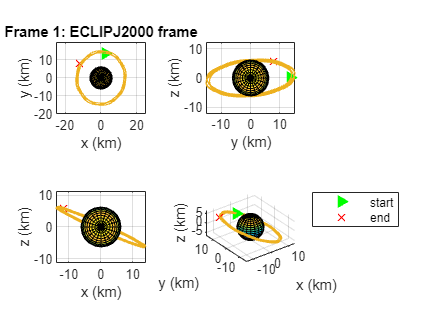

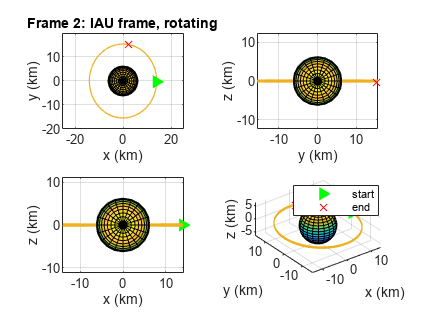

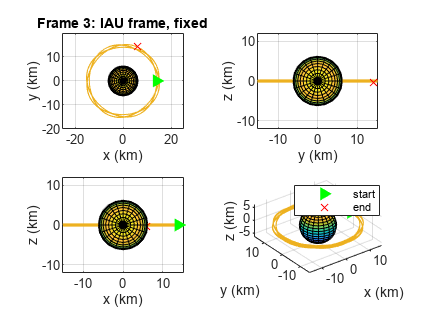

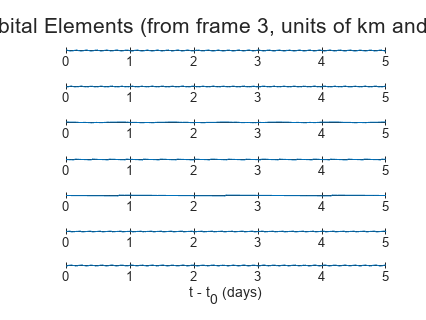

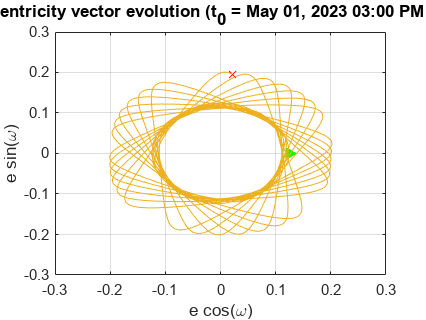

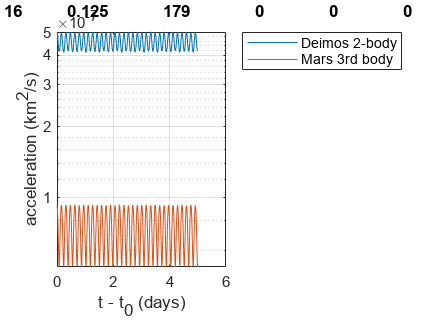

TOF = 5;
OE_initial(3) = 179;
P.mode = 5;

runAndPlot(TOF, OE_initial, P)